## **Charakterystyki czasowe i częstotliwościowe regulatorów**

**Cel ćwiczenia**

Celem ćwiczenia jest zapoznanie się z charakterystykami czasowymi i częstotliwościowymi podstawowych typów regulatorów ciągłych, omawianych na wykładzie i podczas ćwiczeń audytoryjnych. Podczas ćwiczenia należy zbadać następujące regulatory: PI, PD, PID

Regulator występuje w układzie przed obiektem regulacji

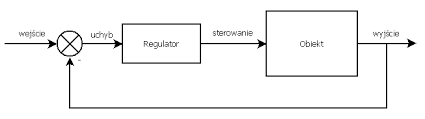

Regulator PI

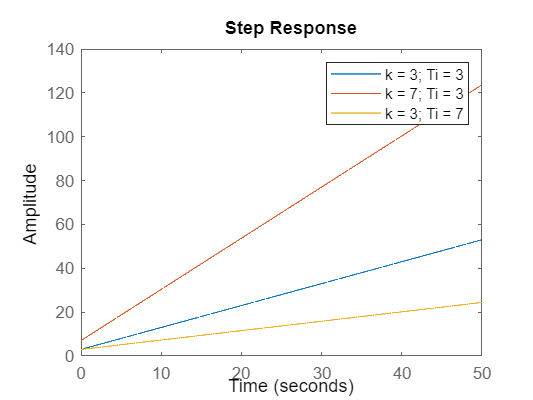

clear;
k = [3 7 3];
Ti = [3 3 7];
figure; hold on;
for i = [1:3]
    G1 = tf([k(i)], [1]); G2 = tf([0 k(i)], [Ti(i) 0]);
    step(G1 + G2);
end
hold off;
legend("k = 3; Ti = 3", "k = 7; Ti = 3", "k = 3; Ti = 7");

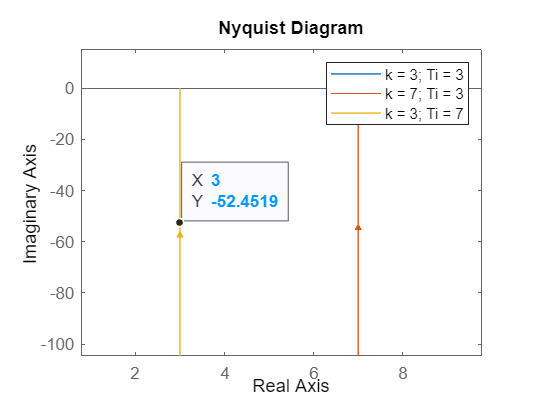


figure; hold on;
    plotoptions = nyquistoptions('cstprefs');
    plotoptions.ShowFullContour = 'off';
for i = [1:3]
     G1 = tf([k(i)], [1]); G2 = tf([0 k(i)], [Ti(i) 0]);
    nyquist(G1 + G2, plotoptions)
end
hold off;
legend("k = 3; Ti = 3", "k = 7; Ti = 3", "k = 3; Ti = 7");

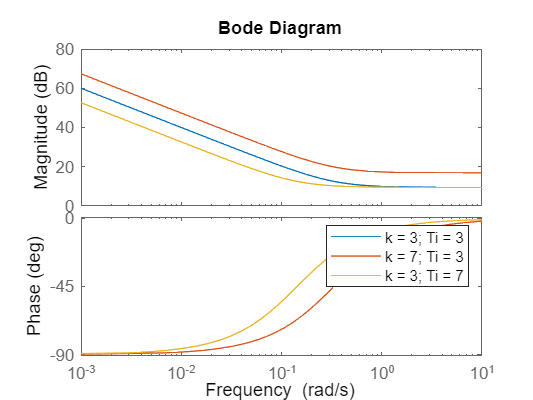


figure; hold on;
for i = [1:3]
     G1 = tf([k(i)], [1]); G2 = tf([0 k(i)], [Ti(i) 0]);
    bode(G1 + G2)
end
hold off;
legend("k = 3; Ti = 3", "k = 7; Ti = 3", "k = 3; Ti = 7");

Regulator PD

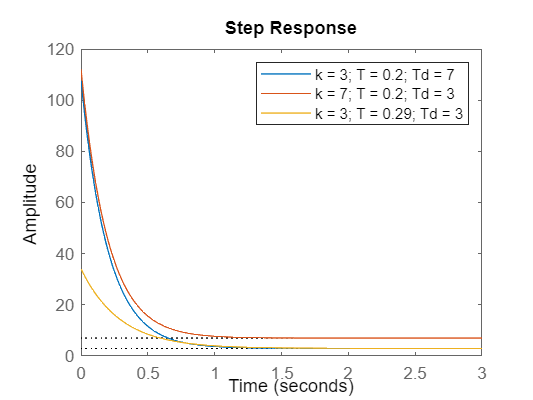

clear;
k = [3 7 3];
T = [0.2 0.2 0.29];
Td = [7 3 3];
figure; hold on;
for i = [1:3]
    G1 = tf([k(i)], [1]); G2 = tf([k(i) * Td(i) 0], [T(i) 1]);
    step(G1 + G2);
end
hold off;
legend("k = 3; T = 0.2; Td = 7", "k = 7; T = 0.2; Td = 3", "k = 3; T = 0.29; Td = 3");

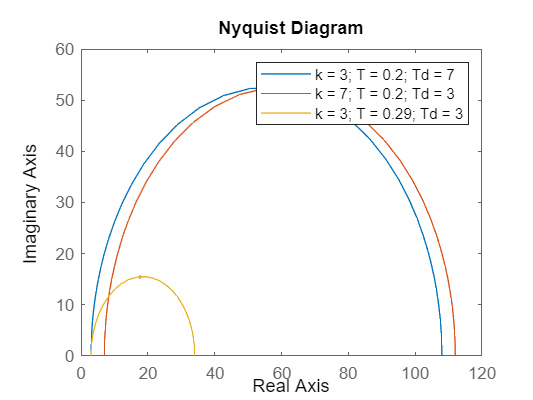


figure; hold on;
    plotoptions = nyquistoptions('cstprefs');
    plotoptions.ShowFullContour = 'off';
for i = [1:3]
    G1 = tf([k(i)], [1]); G2 = tf([k(i) * Td(i) 0], [T(i) 1]);
    nyquist(G1 + G2, plotoptions)
end
hold off; axis([0 120 0 60]);
legend("k = 3; T = 0.2; Td = 7", "k = 7; T = 0.2; Td = 3", "k = 3; T = 0.29; Td = 3")

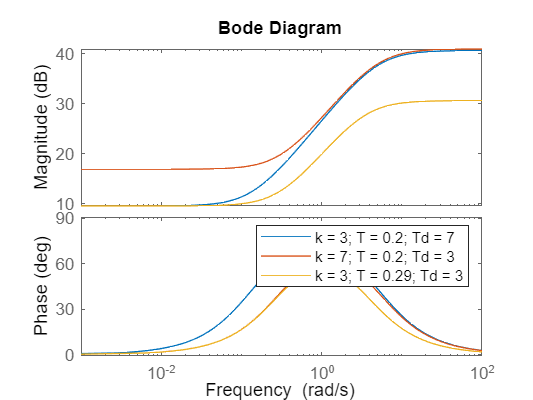


figure; hold on;
for i = [1:3]
    G1 = tf([k(i)], [1]); G2 = tf([k(i) * Td(i) 0], [T(i) 1]);
    bode(G1 + G2)
end
hold off;
legend("k = 3; T = 0.2; Td = 7", "k = 7; T = 0.2; Td = 3", "k = 3; T = 0.29; Td = 3")

Regulator PID

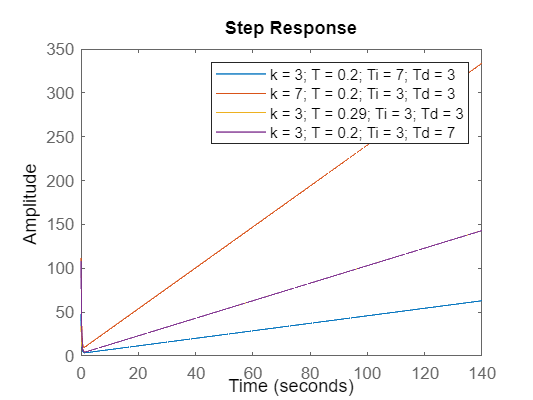

clear;
k = [3 7 3 3];
T = [0.2 0.2 0.29 0.2];
Ti = [7 3 3 3];
Td = [3 3 3 7];
figure; hold on;
for i = [1:4]
    G1 = tf([k(i)], [1]);
    G2 = tf([k(i) * Td(i) 0], [T(i) 1]);
    G3 = tf([0 k(i)], [Ti(i) 0]);
    step(G1 + G2 + G3);
end
hold off;
legend("k = 3; T = 0.2; Ti = 7; Td = 3", "k = 7; T = 0.2; Ti = 3; Td = 3", "k = 3; T = 0.29; Ti = 3; Td = 3", "k = 3; T = 0.2; Ti = 3; Td = 7");

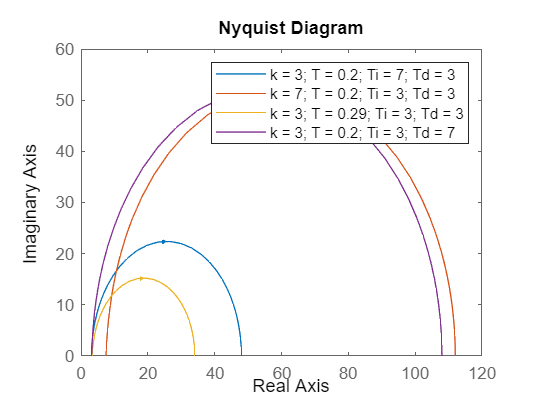


figure; hold on;
    plotoptions = nyquistoptions('cstprefs');
    plotoptions.ShowFullContour = 'off';
for i = [1:4]
    G1 = tf([k(i)], [1]);
    G2 = tf([k(i) * Td(i) 0], [T(i) 1]);
    G3 = tf([0 k(i)], [Ti(i) 0]);
    nyquist(G1 + G2 + G3, plotoptions)
end
hold off;  axis([0 120 0 60]);
legend("k = 3; T = 0.2; Ti = 7; Td = 3", "k = 7; T = 0.2; Ti = 3; Td = 3", "k = 3; T = 0.29; Ti = 3; Td = 3", "k = 3; T = 0.2; Ti = 3; Td = 7");

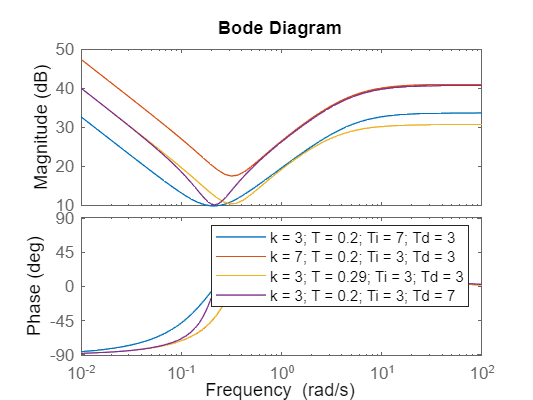


figure; hold on;
for i = [1:4]
    G1 = tf([k(i)], [1]);
    G2 = tf([k(i) * Td(i) 0], [T(i) 1]);
    G3 = tf([0 k(i)], [Ti(i) 0]);
    bode(G1 + G2 + G3)
end
hold off;
legend("k = 3; T = 0.2; Ti = 7; Td = 3", "k = 7; T = 0.2; Ti = 3; Td = 3", "k = 3; T = 0.29; Ti = 3; Td = 3", "k = 3; T = 0.2; Ti = 3; Td = 7");

**Wnioski**

Ćwiczenie pozwoliło na zapoznanie się charakterystykami częstotliwościowymi Nyquista i Bodego oraz odpowiedziami skokowymi różnego typu regulatorów liniowych. Umożliwiło również analizę wpływu jaki na nie mają wartości parametrów obiektów.

Przykładowo:

W regulatorze PI, wzrost k, w odpowiedzi skokowej, zwiększa wartość w t = 0 i nachylenie odpowiedzi i przesuwa w prawo punkt końcowy char. Nyquista. Wzrost Ti, zmniejsza nachylenie odp. skokowej i przesuwa w lewo charakterystykę Bodego

W PD, wzrost T zmniejsza wartość w t = 0 odp. skokowej i przesuwa w lewo punkt końcowy char. Nyquista (zmniejsza pole obejmowane przez wykres). Wzrost Td obniża wartość na wyjści regulatora po ustaleniu się odpowiedzi skokowej oraz zwiększa nachylenia w char. Bodego